# Model Evaluation

## ***Naive Bayes evaluation:***

***Model Building***

tic
Mdl_NB = fitcnb([trainingSetPCA;testingSetPCA], [trainingSetTargetPCA;testingSetTargetPCA]);
Mdl_NB_CV = crossval(Mdl_NB, 'KFold', 10);
tTrain_NB = toc

tTrain_NB = 3.7943

## `Calculating Accuracy`

disp('Accuracy of the cross-validated model is')

Accuracy of the cross-validated model is


tic
accuracy_NB = 1-kfoldLoss(Mdl_NB_CV)

accuracy_NB = 0.5796

[Label_NB,Score_NB] = kfoldPredict(Mdl_NB_CV);
tTest_NB = toc

tTest_NB = 2.3139

## `Calculating DCG score`

[DCG_NB, NDCG_NB] = dcgScore([trainingSetTargetPCA;testingSetTargetPCA], Score_NB, 5);
disp('NDCG score of the Naive Bayes model is: ')

NDCG score of the Naive Bayes model is: 


NDCG_NB

NDCG_NB = 0.8054

## `ROC curve`

[FP_NB_US,TP_NB_US,AUC_NB_US] = perfcurve([trainingSetTargetPCA;testingSetTargetPCA],Score_NB(:,11),11); %11 is the index of US
[FP_NB_NDF,TP_NB_NDF,AUC_NB_NDF] = perfcurve([trainingSetTargetPCA;testingSetTargetPCA],Score_NB(:,8),8); %8 is the index of NDF
[FP_NB_FR,TP_NB_FR,AUC_NB_FR] = perfcurve([trainingSetTargetPCA;testingSetTargetPCA],Score_NB(:,5),5); %5 is the index of FR
[FP_NB_AU,TP_NB_AU,AUC_NB_AU] = perfcurve([trainingSetTargetPCA;testingSetTargetPCA],Score_NB(:,1),1); %1 is the index of AU

## ***Decision Trees evaluation:***

***Model Building***

trainingSetDT = trainingSet(:,1:12);
testingSetDT  = testingSet(:,1:12);
tic
Mdl_Tree = fitctree([trainingSetDT;testingSetDT], [trainingSetTarget;testingSetTarget],...
    'SplitCriterion','twoing','MaxNumSplits',22,'MinLeafSize',1,'CrossVal','on');
tTrain_Tree = toc

tTrain_Tree = 9.8782

## `Calculating Accuracy`

disp('Accuracy of the cross-validated model is')

Accuracy of the cross-validated model is


tic
accuracy_Tree = 1-kfoldLoss(Mdl_Tree)

accuracy_Tree = 0.6220

[Label_Tree,Score_Tree] = kfoldPredict(Mdl_Tree);
tTest_Tree = toc

tTest_Tree = 2.0361

## `Calculating DCG score`

[DCG_Tree, NDCG_Tree] = dcgScore([trainingSetTarget;testingSetTarget], Score_Tree, 5);
disp('NDCG score of the Decision Tree model is: ')

NDCG score of the Decision Tree model is: 


NDCG_Tree

NDCG_Tree = 0.8208

## `ROC curve`

[FP_Tree_US,TP_Tree_US,AUC_Tree_US] = perfcurve([trainingSetTarget;testingSetTarget],Score_Tree(:,11),11); %11 is the index of US
[FP_Tree_NDF,TP_Tree_NDF,AUC_Tree_NDF] = perfcurve([trainingSetTarget;testingSetTarget],Score_Tree(:,8),8); %8 is the index of NDF
[FP_Tree_FR,TP_Tree_FR,AUC_Tree_FR] = perfcurve([trainingSetTarget;testingSetTarget],Score_Tree(:,5),5); %5 is the index of FR
[FP_Tree_AU,TP_Tree_AU,AUC_Tree_AU] = perfcurve([trainingSetTarget;testingSetTarget],Score_Tree(:,1),1); %1 is the index of AU

## ***kNearest Neighbor evaluation:***

***Model Building***

tic
Mdl_kNN = fitcknn([trainingSetPCA;testingSetPCA],[trainingSetTargetPCA;testingSetTargetPCA],...
    'NumNeighbors',100,'CrossVal','on');
tTrain_kNN = toc

tTrain_kNN = 3.2486

## `Calculating Accuracy`

disp('Accuracy of the cross-validated model is')

Accuracy of the cross-validated model is


tic
accuracy_kNN = 1-kfoldLoss(Mdl_kNN)

accuracy_kNN = 0.5839

[Label_kNN,Score_kNN] = kfoldPredict(Mdl_kNN);
tTest_kNN = toc

tTest_kNN = 8.0158

## `Calculating DCG score`

[DCG_kNN, NDCG_kNN] = dcgScore([trainingSetTarget;testingSetTarget], Score_kNN, 5);
disp('NDCG score of the Decision kNN model is: ')

NDCG score of the Decision kNN model is: 


NDCG_kNN

NDCG_kNN = 0.8042

## `ROC curve`

[FP_kNN_US,TP_kNN_US,AUC_kNN_US] = perfcurve([trainingSetTarget;testingSetTarget],Score_kNN(:,11),11); %11 is the index of US
[FP_kNN_NDF,TP_kNN_NDF,AUC_kNN_NDF] = perfcurve([trainingSetTarget;testingSetTarget],Score_kNN(:,8),8); %8 is the index of NDF
[FP_kNN_FR,TP_kNN_FR,AUC_kNN_FR] = perfcurve([trainingSetTarget;testingSetTarget],Score_kNN(:,5),5); %5 is the index of FR
[FP_kNN_AU,TP_kNN_AU,AUC_kNN_AU] = perfcurve([trainingSetTarget;testingSetTarget],Score_kNN(:,1),1); %1 is the index of AU

## ***Ensemble Model evaluation:***

***Model Building***

tic
Mdl_Ens = fitcensemble([trainingSet;testingSet],[trainingSetTarget;testingSetTarget],...
    'Method','AdaBoostM2','CrossVal','on');
tTrain_Ens = toc

tTrain_Ens = 971.1049

## `Calculating Accuracy`

disp('Accuracy of the cross-validated model is')

Accuracy of the cross-validated model is


tic
accuracy_Ens = 1-kfoldLoss(Mdl_Ens)

accuracy_Ens = 0.6226

[Label_Ens,Score_Ens] = kfoldPredict(Mdl_Ens);
tTest_Ens = toc

tTest_Ens = 51.8836

## `Calculating DCG score`

[DCG_Ens, NDCG_Ens] = dcgScore([trainingSetTarget;testingSetTarget], Score_Ens, 5);
disp('NDCG score of the Decision Ens model is: ')

NDCG score of the Decision Ens model is: 


NDCG_Ens

NDCG_Ens = 0.8212

## `ROC curve`

[FP_Ens_US,TP_Ens_US,AUC_Ens_US] = perfcurve([trainingSetTarget;testingSetTarget],Score_Ens(:,11),11); %11 is the index of US
[FP_Ens_NDF,TP_Ens_NDF,AUC_Ens_NDF] = perfcurve([trainingSetTarget;testingSetTarget],Score_Ens(:,8),8); %8 is the index of NDF
[FP_Ens_FR,TP_Ens_FR,AUC_Ens_FR] = perfcurve([trainingSetTarget;testingSetTarget],Score_Ens(:,5),5); %5 is the index of FR
[FP_Ens_AU,TP_Ens_AU,AUC_Ens_AU] = perfcurve([trainingSetTarget;testingSetTarget],Score_Ens(:,1),1); %1 is the index of AU

## Comparison

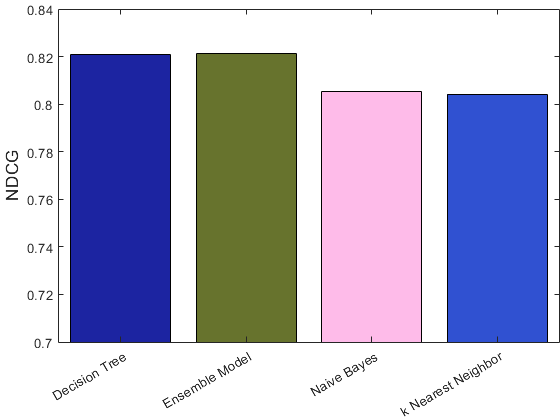

labels = categorical({'Naive Bayes','Decision Tree','k Nearest Neighbor', 'Ensemble Model'});
Colors=rand(4,3);
b=bar(labels,[NDCG_NB,NDCG_Tree,NDCG_kNN,NDCG_Ens],'FaceColor','flat');
b.CData=Colors;
ylim([0.7,0.84]);
ylabel('NDCG','FontSize',13);
removewhitespace;

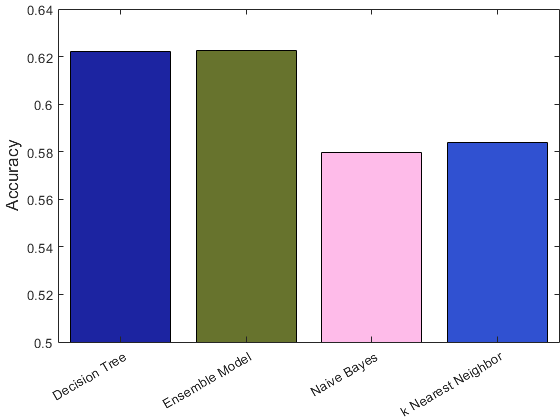

b=bar(labels,[accuracy_NB,accuracy_Tree,accuracy_kNN,accuracy_Ens],'FaceColor','flat');
b.CData=Colors;
ylim([0.5,0.64]);
ylabel('Accuracy','FontSize',13);
removewhitespace;

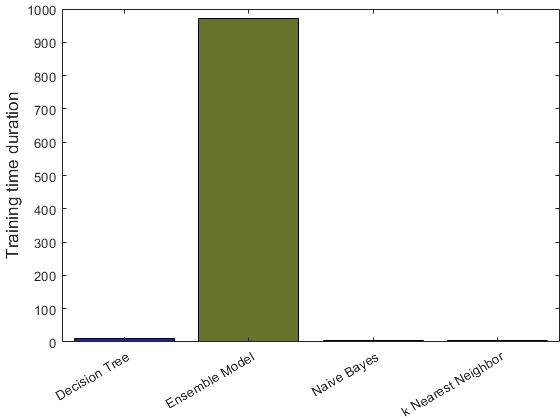

b=bar(labels,[tTrain_kNN,tTrain_Tree,tTrain_kNN,tTrain_Ens],'FaceColor','flat');
b.CData=Colors;
ylabel('Training time duration','FontSize',13);
removewhitespace;

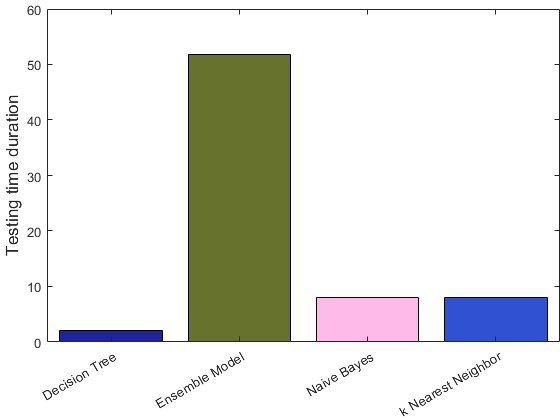

b=bar(labels,[tTest_kNN,tTest_Tree,tTest_kNN,tTest_Ens],'FaceColor','flat');
b.CData=Colors;
ylabel('Testing time duration','FontSize',13);
removewhitespace;

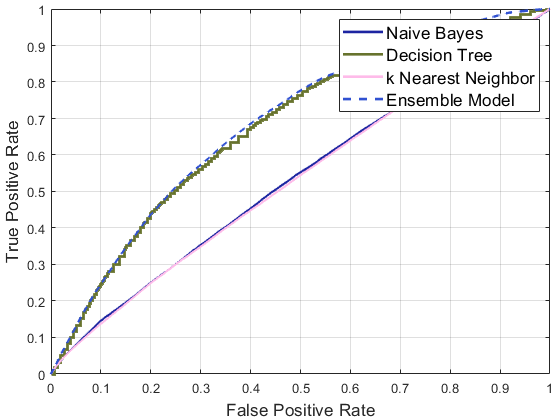

figure;
stairs(FP_NB_US,TP_NB_US,'Color',Colors(1,:),'LineWidth',2);
hold on;
stairs(FP_Tree_US,TP_Tree_US,'Color',Colors(2,:),'LineWidth',2);
stairs(FP_kNN_US,TP_kNN_US,'Color',Colors(3,:),'LineWidth',2);
stairs(FP_Ens_US,TP_Ens_US,'--','Color',Colors(4,:),'LineWidth',2);
xlabel('False Positive Rate','FontSize',13);
ylabel('True Positive Rate','FontSize',13);
legend({'Naive Bayes','Decision Tree','k Nearest Neighbor', 'Ensemble Model'},'FontSize',13);
grid on;
removewhitespace;